# Getting started with the Computational Physiology Toolbox

The Computational Physiology Toolbox provides an easy-to-use scripting interface to define and execute physiology-based modelling workflows.

### Setup

Once the Computational Physiology Toolbox is downloaded and installed, you have to initialize the toolbox (this loads the unit computation system, the physiology database and the drug database into memory):

initcompphysiol()



 --------------------------------------------------------------- 
|         compphysiol: Computational Physiology Toolbox         |
|                                                               |
|             (c) Niklas Hartung, Wilhelm Huisinga              |
|                   University of Potsdam, 2024                 |
|                                                               |
|  The program is distributed under the terms of the            |
|  BSD 2-Clause License (see file license.txt).                 |
|                                                               |
 --------------------------------------------------------------- 


Initializing units ... finished.

Initializing the physiological database ... finished.
The following reference individuals are defined:
    {'rat250'  }
    {'rat475'  }
    {'mouse25' }
    {'mouse40' }
    {'human0u' }
    {'human1u' }
    {'human5u' }
    {'human10u'}
    {'human15m'}
    {'human15f'}
    {'human35m'}
    {'human3

### Example usage

Below is a simple script to define and run a PBPK model simulation. More complex simulation scripts can found in the `examples` folder.

Define physiology, dosing, sampling, model

obs = PBPKobservables();
indv = Individual('Virtual');
indv.physiology = Physiology('human35m');
indv.dosing = Oral('Warfarin',(0:7)*u.day, 250*u.mg);
indv.drugdata = loaddrugdata('Warfarin','species','human');
indv.sampling = Sampling(2*u.day:30*u.min:8*u.day, obs);
indv.model = sMD_PBPK_12CMT_wellstirred;
indv.model.options.tissuePartitioning = @rodgersrowland;

Next, initialize, simulate, plot:

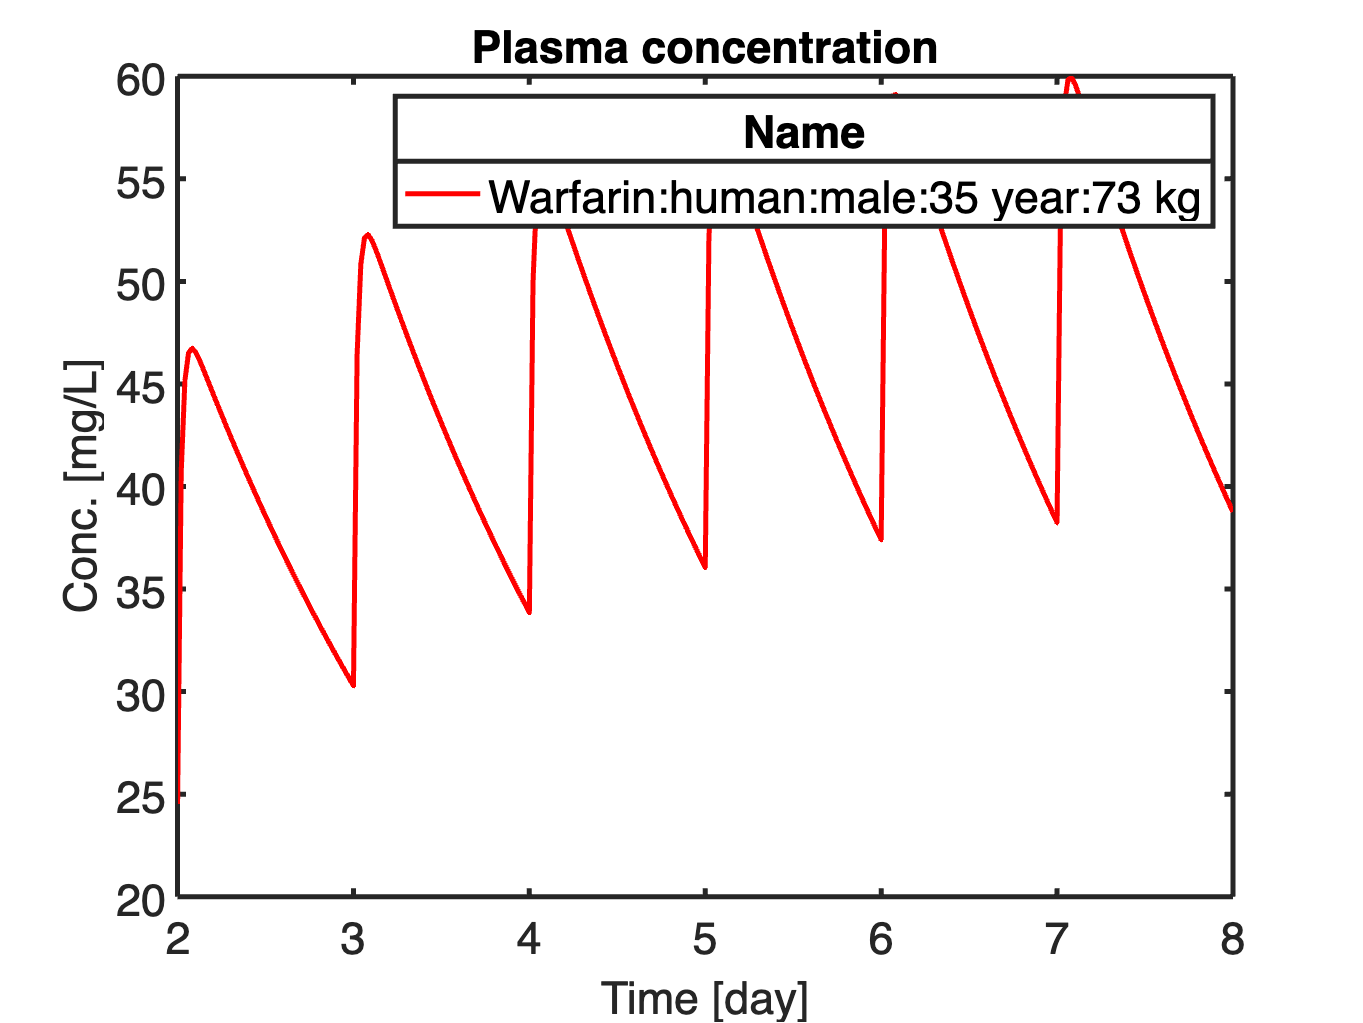

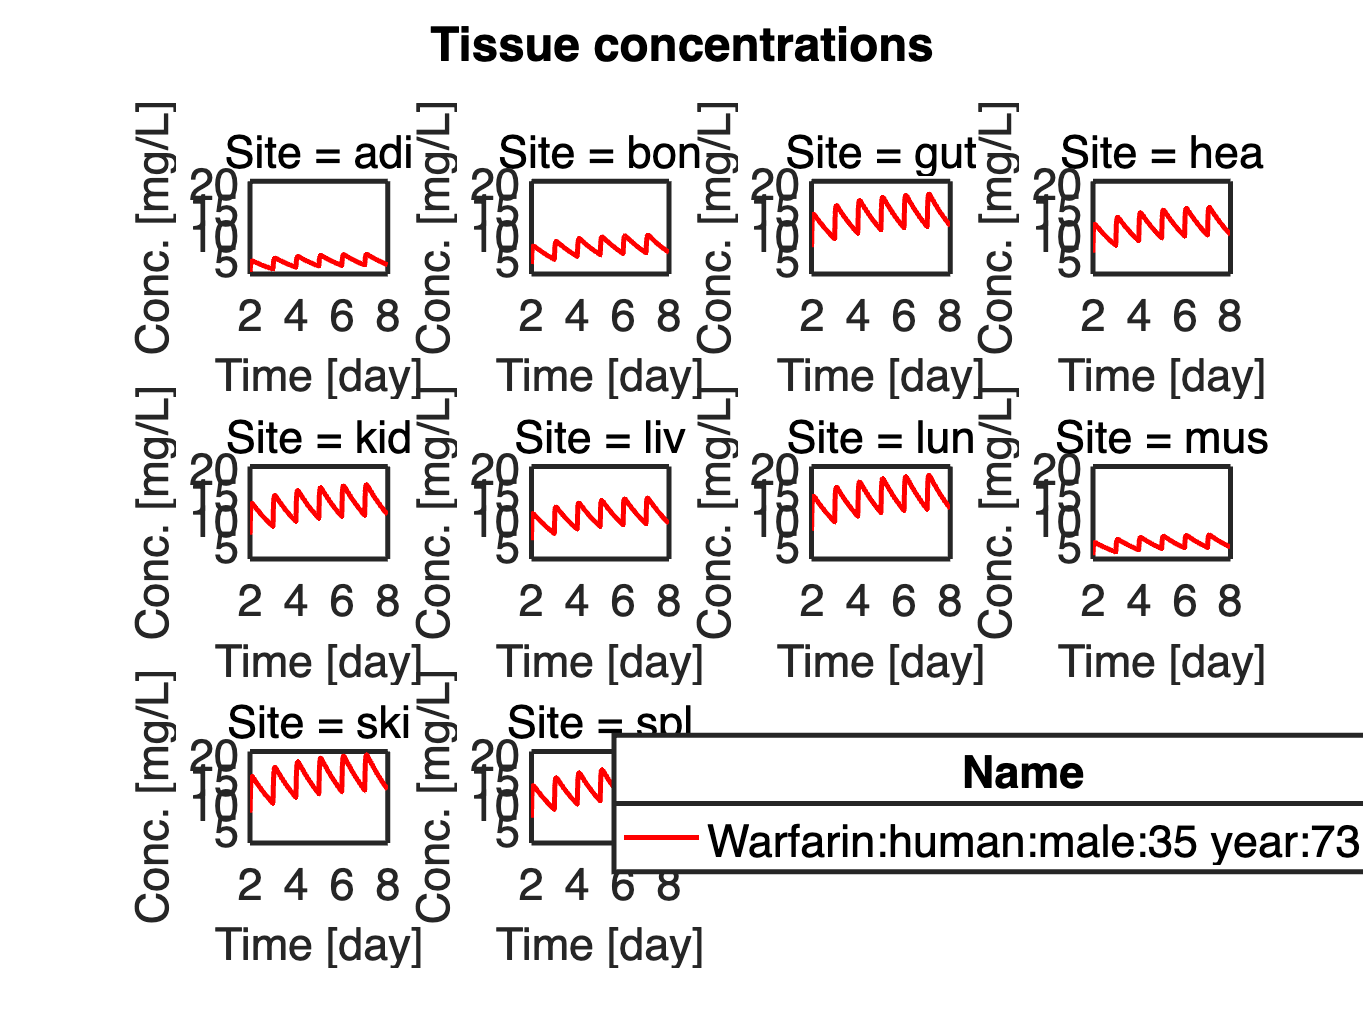

initialize(indv)
simulate(indv)
plot(indv, 'yunit', 'mg/L')